# uix.Panel 

Arrange a single element inside a standard panel

## Syntax

## Description

`p = uix.Panel()` creates a standard [`uipanel`](matlab:doc uipanel) object but with automatic management of the contained widget or layout. The properties available are largely the same as the builtin [`uipanel`](matlab:doc uipanel) object. Where more than one child is added, the currently visible child is determined using the Selection property.

`obj = uix.Panel(Name,Value)` also sets one or more property values.

## **Properties**

### Title

#### `Title` **—** **Title**

character vector | string scalar | categorical array

Title, specified as a character vector, string scalar, or categorical array. If you specify this property as a categorical array, MATLAB® displays only the first element in the array.

MATLAB does not interpret a vertical slash (`'|'`) character as a line break, it displays as a vertical slash in the title.

If you want to specify a Unicode® character, pass the Unicode decimal code to the [`char`](https://localhost:31515/static/help/matlab/ref/char.html) function. For example, `['Multiples of ' char(960)]` displays as `Multiples of` *π*.

#### `TitlePosition` **—** **Location of title**

`'lefttop'` (default) | `'centertop'` | `'righttop'`

Location of the title, specified as `'lefttop'`, `'centertop'`, or `'righttop'`.

### Color and Styling

#### `ForegroundColor` **—** **Title color**

`[0 0 0]` (default) | RGB triplet | hexadecimal color code | `'r'` | `'g'` | `'b'` | ...

Title color, specified as an RGB triplet, a hexadecimal color code, or one of the color options listed in the table.

RGB triplets and hexadecimal color codes are useful for specifying custom colors.

- An RGB triplet is a three-element row vector whose elements specify the intensities of the red, green, and blue components of the color. The intensities must be in the range `[0,1]`; for example, `[0.4 0.6 0.7]`.

- A hexadecimal color code is a character vector or a string scalar that starts with a hash symbol (`#`) followed by three or six hexadecimal digits, which can range from `0` to `F`. The values are not case sensitive. Thus, the color codes `'#FF8800'`, `'#ff8800'`, `'#F80'`, and `'#f80'` are equivalent.

Alternatively, you can specify some common colors by name. This table lists the named color options, the equivalent RGB triplets, and hexadecimal color codes.

#### `BackgroundColor` **—** **Background color**

`[.94 .94 .94]` (default) | RGB triplet | hexadecimal color code | `'r'` | `'g'` | `'b'` | ...

Background color, specified as an RGB triplet, a hexadecimal color code, or one of the color options listed in the table.

RGB triplets and hexadecimal color codes are useful for specifying custom colors.

- An RGB triplet is a three-element row vector whose elements specify the intensities of the red, green, and blue components of the color. The intensities must be in the range `[0,1]`; for example, `[0.4 0.6 0.7]`.

- A hexadecimal color code is a character vector or a string scalar that starts with a hash symbol (`#`) followed by three or six hexadecimal digits, which can range from `0` to `F`. The values are not case sensitive. Thus, the color codes `'#FF8800'`, `'#ff8800'`, `'#F80'`, and `'#f80'` are equivalent.

Alternatively, you can specify some common colors by name. This table lists the named color options, the equivalent RGB triplets, and hexadecimal color codes.

#### `BorderType` **—** **Panel border**

`'line'` (default) | `'none'`

Panel border, specified as `'line'` or `'none'`.

### Legacy

`BackgroundColor `[`colorspec`](matlab:doc colorspec)Color to use for exposed areas of the layout background. This can be an RGB triple (e.g. [0 0 1]) or a colour name (e.g. 'b').

`BeingDeleted `on | offDeletion status.

`BorderType `none | etchedin | etchedout | beveledin | beveledout | lineType of border around the uipanel area.

`BorderWidth `positive integerWidth of the panel border.

`Contents `empty GraphicsPlaceholder array | array of graphics objectsChildren within this layout, regardless of HandleVisibility. Note that this can only be set to permutations of itself.

`DeleteFcn `[`function_handle`](matlab:doc function_handle)Function to call when the layout is being deleted.

`FontAngle `normal | italic | obliqueTitle font angle.

`FontName `stringTitle font name (e.g. Arial, Helvetica etc).

`FontSize `positive integerTitle font size.

`FontUnits `inches | centimeters | normalized | points | pixelsTitle font units for measuring size.

`FontWeight `light | normal | demi | boldTitle font weight.

`ForegroundColor `[`colorspec`](matlab:doc colorspec)Title font color and/or color of 2-D border line.

`HighlightColor `[`colorspec`](matlab:doc colorspec)3-D frame highlight color.

`Padding `positive integerNumber of pixels of extra space around the outside of the layout.

`Parent `empty GraphicsPlaceholder array | figure | containerParent of the layout.

`Position `[x y w h]Position (x,y) and size (w,h) within figure or container.

`Selection `positive integer or emptyWhich child is visible.

`ShadowColor `[`colorspec`](matlab:doc colorspec)3-D frame shadow color.

`Tag `stringTag to associate with layout.

`Title `stringTitle string.

`TitlePosition `lefttop | centertop | righttop | leftbottom | centerbottom | rightbottomLocation of title string in relation to the panel.

`Type `stringType of graphics object.

`Units `inches | centimeters | normalized | points | pixels | charactersPosition units.

`Visible `on | offVisibility.

## **Examples**

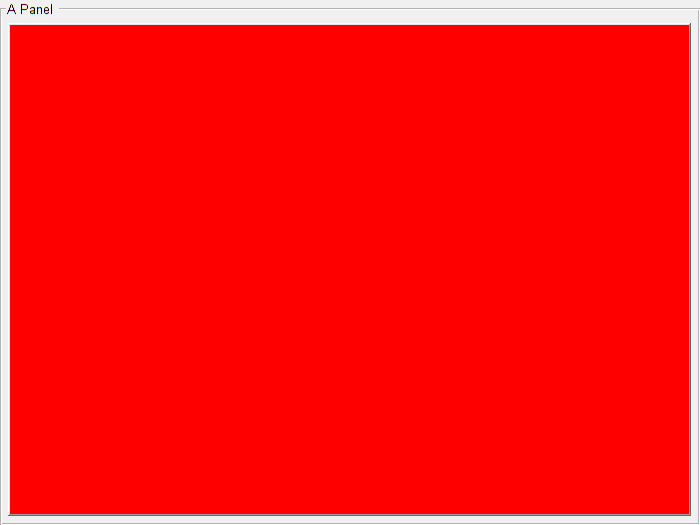

f = figure();
p = uix.Panel( 'Parent', f, 'Title', 'A Panel', 'Padding', 5 );
uicontrol( 'Parent', p, 'Background', 'r' )

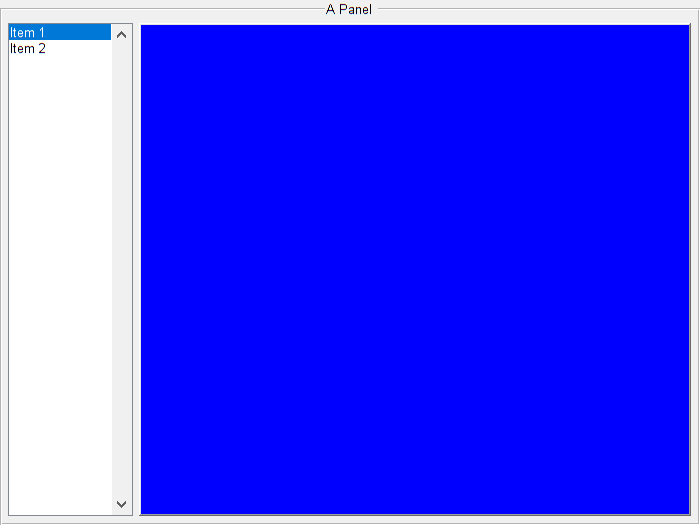

f = figure();
p = uix.Panel( 'Parent', f, 'Title', 'A Panel', 'TitlePosition', 'CenterTop');
b = uix.HBox( 'Parent', p, 'Spacing', 5, 'Padding', 5  );
uicontrol( 'Style', 'listbox', 'Parent', b, 'String', {'Item 1','Item 2'} );
uicontrol( 'Parent', b, 'Background', 'b' );
set( b, 'Widths', [100 -1] );